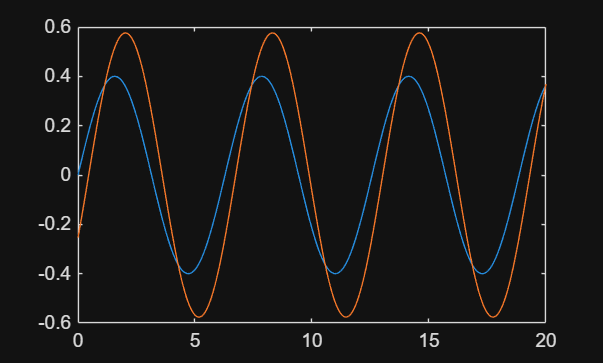

K = 1;
M = 1;
B = 2;
t = [0:0.01:20];
u = 0.4*sin(t);

numPF = [1];
denPF = [M B K];

Gpf = tf(numPF, denPF);

GPI = tf([10 5], [1 0]);
GPID = tf([2 10 5], [0.01 1 0]);

Gd = series(Gpf, GPI);
G0 = feedback(Gd, 1);

[a, f] = bode(G0, 2);
y = 0.4*a*sin(t + deg2rad(f));
plot(t,u,t,y)

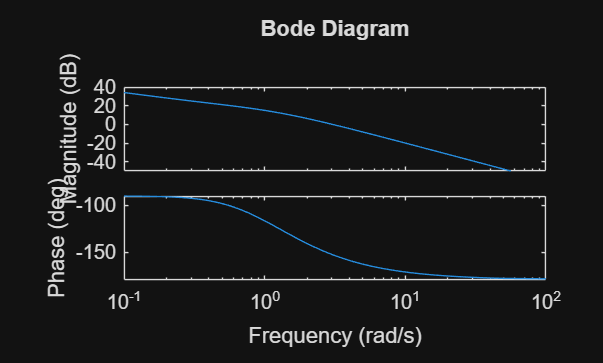


bode(Gd)

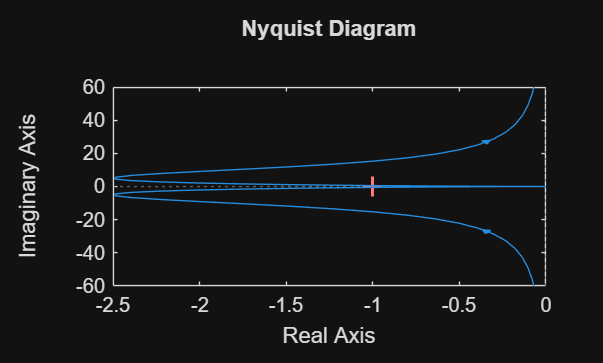

nyquist(Gd)

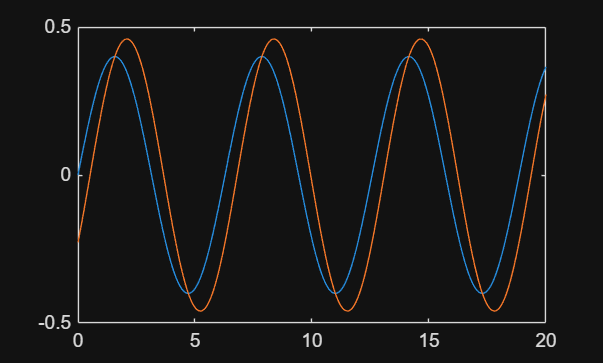

Gd = series(Gpf, GPID);
G0 = feedback(Gd, 1);

[a, f] = bode(G0, 2);
y = 0.4*a*sin(t + deg2rad(f));
plot(t,u,t,y)

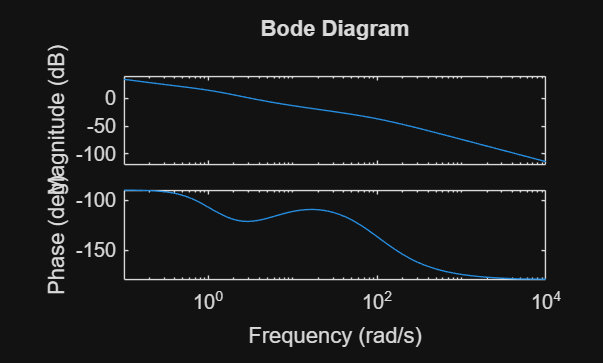


bode(Gd)

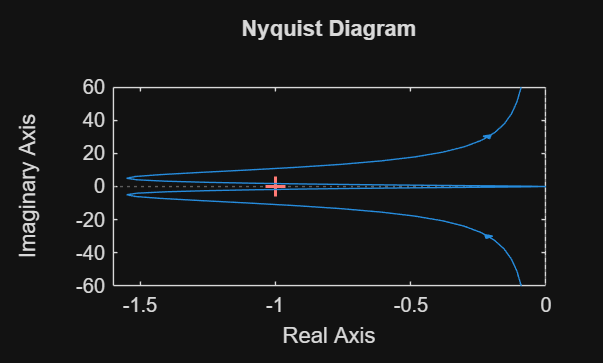

nyquist(Gd)